Fs = 8000

Fs = 8000


fileID = fopen('random.dat','r');
random_signal = fscanf(fileID,'%f\n');
f1 = Fs*(0:(length(random_signal) - 1))/length(random_signal)

f1 = 	1.0e+03 *

         0    0.0008    0.0016    0.0024    0.0032    0.0040    0.0048    0.0056    0.0064    0.0072    0.0080    0.0088    0.0096    0.0104    0.0112    0.0120    0.0128    0.0136    0.0144    0.0152    0.0160    0.0168    0.0176    0.0184    0.0192    0.0200    0.0208    0.0216    0.0224    0.0232    0.0240    0.0248    0.0256    0.0264    0.0272    0.0280    0.0288    0.0296    0.0304    0.0312    0.0320    0.0328    0.0336    0.0344    0.0352    0.0360    0.0368    0.0376    0.0384    0.0392


fclose(fileID);

fileID = fopen('filtered_signal.dat','r');
filtered_signal = fscanf(fileID,'%f\n');
f2 = Fs*(0:(length(filtered_signal) - 1))/length(filtered_signal)

f2 = 	1.0e+03 *

         0    0.0008    0.0016    0.0024    0.0032    0.0040    0.0048    0.0056    0.0064    0.0072    0.0080    0.0088    0.0096    0.0104    0.0112    0.0120    0.0128    0.0136    0.0144    0.0152    0.0160    0.0168    0.0176    0.0184    0.0192    0.0200    0.0208    0.0216    0.0224    0.0232    0.0240    0.0248    0.0256    0.0264    0.0272    0.0280    0.0288    0.0296    0.0304    0.0312    0.0320    0.0328    0.0336    0.0344    0.0352    0.0360    0.0368    0.0376    0.0384    0.0392


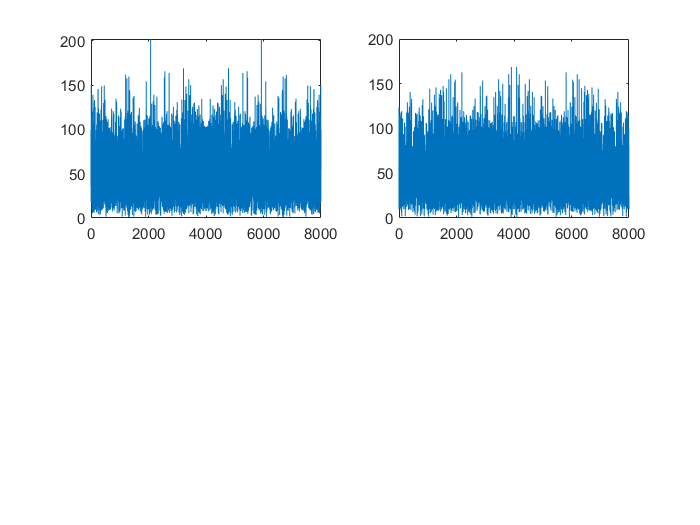

fclose(fileID);

random_signal_spectrum = abs(fftshift(fft(random_signal)));
filtered_signal_spectrum = abs(fftshift(fft(filtered_signal)));

figure
subplot(2,2,1)
plot(f1, random_signal_spectrum)
subplot(2,2,2)
plot(f2, filtered_signal_spectrum)